# Liniowe systemy dynamiczne: transmitancja, odpowiedź impulsowa, charakterystyki częstotliwościowe

Krzysztof Arent

2024

## laboratorium

#### imię i nazwisko studenta: Kacper Karkosz, Aleksander Łyskawa

### Zadanie 1

System dynamiczny rozumiemy jako odwzorowanie przekształcające sygnały mające sens pobudzeń  (oddziaływujących na system) na przestrzeń sygnałów mających sens reakcji systemu na pobudzenia. Takie odwzorowanie może być zdefiniowane na wiele sposobów, co prowadzi do wielu równoważnych reprezentacji tego samego odwzorowania. Pod pojęciem reprezentacji równoważnych rozumiemy równoważność wejściowo-wyjściową.

Modelowanie z praw podstawowych (np. prawa dynamiki Newtona, prawa Ohma i Kirchhoffa) prowadzi do modeli matematycznych systemów dynamicznych w postaci równań różniczkowych. Te równania można przekształcać do rozmaitych postaci, np. prawidłowo eliminując z nich wybrane zmienne czy rozszerzając je o zmienne stanu. Jeżeli równania różniczkowe są liniowe to można je przekształcić z dziedziny czasu do dziedziny częstotliwości stosując np. transformatę Laplacea. Wtedy system dynamiczny będzie reprezentowany przez transmitancję a problemy związane z równaniami różniczkowymi zostaną zamienione na problemy z algebry i analizy zespolonej. Taka zmiana perspektywy często ułatwia badanie danego systemu dzięki możliwości zastosowania narzędzi matematycznych właściwych dla tej perspektywy.

Rozważmy równanie różniczkowe dwóch zmiennych


$$\ddot{y}(t)+a_1 \dot{y}(t) + a_0 y(t) = b_0 u(t) \quad (1)$$


Przyjąć $a_1=3, ~a_0=2, ~b_0=2.$  

Dokonać transformaty Laplace'a (symboliczne) lewej i prawej strony równania (1) dla przypadku gdy $y(0)=0, ~\dot{y}(0)=0$ Wyznaczyć transmitancję $G(s)$ systemu reprezentowanego przez (1). Niech $u(t)=\sin(\frac{1}{3}t)$ dla $t \geq 0$. Wyznaczyć $U(s)=\mathcal{L}\{ u(t) \}$, $Y(s)=G(s) \cdot U(s)$ i na koniec obliczyć $y_G(t)=\mathcal{L}^{-1} (Y(s))$.  Przedstawić na jednym wykresie przebieg czasowy $y_G(t)$ oraz przebieg czasowy rozwiązania $y(t)$ dla $t \in [0,50]$ równania różniczkowego (1).

Powyższe zadanie można zrealizować w sposób następujący:

clear all
close all
% deklaracja zmiennych i funkcji symbolicznych (obiektów klasy sym)
syms t y(t) u(t) s Y(s) U(s)  

% definicje parametrów równania różniczkowego (1)
a1=3;
a0=2;
b0=2;
% implementacja równania różniczkowego (1)
rownanie=diff(y(t),t,2)+a1*diff(y(t),t,1)+a0*y(t)== b0*u(t)

$$rownanie = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+3\,\frac{\partial }{\partial t}y\left(t\right)+2\,y\left(t\right)=2\,u\left(t\right)$$

% specyfikacja warunków początkowych równania różniczkowego (1)
wp={0,0} % wp{1}=y(0), wp{2}=y'(0)

wp = 1×2 cell array
    {[0]}    {[0]}


% przekształcanie równania (1) przez transformatę Laplace'a
rownanieL=laplace(rownanie,t,s)

$$rownanieL = 3\,s\,\mathrm{laplace}\left(y\left(t\right),t,s\right)-3\,y\left(0\right)-s\,y\left(0\right)-\left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)+s^{2}\,\mathrm{laplace}\left(y\left(t\right),t,s\right)+2\,\mathrm{laplace}\left(y\left(t\right),t,s\right)=2\,\mathrm{laplace}\left(u\left(t\right),t,s\right)$$

rownanieL=subs(rownanieL,{y(0),subs(diff(y(t),t,1),t,0)},wp)

$$rownanieL = 3\,s\,\mathrm{laplace}\left(y\left(t\right),t,s\right)+s^{2}\,\mathrm{laplace}\left(y\left(t\right),t,s\right)+2\,\mathrm{laplace}\left(y\left(t\right),t,s\right)=2\,\mathrm{laplace}\left(u\left(t\right),t,s\right)$$

rownanieL=subs(rownanieL,{laplace(y(t),t,s), laplace(u(t),t,s)},{Y(s),U(s)})

$$rownanieL = 2\,Y\left(s\right)+3\,s\,Y\left(s\right)+s^{2}\,Y\left(s\right)=2\,U\left(s\right)$$

rownanieL=isolate(rownanieL,Y(s))

$$rownanieL = Y\left(s\right)=\frac{2\,U\left(s\right)}{s^{2}+3\,s+2}$$

% obliczanie transmitancji G(s) o ile jest to możliwe (warunki początkowe
% są zerowe)
if subs(rhs(rownanieL),U(s),0)==0
    rownanieL=rownanieL/U(s)
    G(s)=rhs(rownanieL)
end

$$rownanieL = \frac{Y\left(s\right)}{U\left(s\right)}=\frac{2}{s^{2}+3\,s+2}$$

$$G(s) = \frac{2}{s^{2}+3\,s+2}$$

% definicja zmiennej u w równaniu różniczkowym (1)
u(t)=sin(1/3*t)

$$u(t) = \sin\left(\frac{t}{3}\right)$$

% wyznaczanie reakcji na pobudzenie u(t) przy użyciu transformaty Laplace'a
% i odwrotnej transformaty Laplace'a
U(s)=laplace(u(t),t,s)

$$U(s) = \frac{1}{3\,\left(s^{2}+\frac{1}{9}\right)}$$

Y(s)=G(s)*U(s)

$$Y(s) = \frac{2}{3\,\left(s^{2}+\frac{1}{9}\right)\,\left(s^{2}+3\,s+2\right)}$$

y_G(t)=simplify(ilaplace(Y(s),s,t))

$$y\_G(t) = \frac{3\,{\mathrm{e}}^{-t}}{5}-\frac{81\,\cos\left(\frac{t}{3}\right)}{185}-\frac{6\,{\mathrm{e}}^{-2\,t}}{37}+\frac{153\,\sin\left(\frac{t}{3}\right)}{185}$$

% dla porównania:
% wyznaczanie rozwiązania analitycznego równanania różniczkowego (1) dla ustalonych
% warunków początkowych
war_pocz=[y(0)==wp{1}, subs(diff(y(t),t,1),t,0)==wp{2}]

$$war\_pocz = \left(\begin{array}{cc} y\left(0\right)=0 & \left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)=0 \end{array}\right)$$

rownanie=diff(y(t),t,2)+a1*diff(y(t),t,1)+a0*y(t)== b0*u(t)

$$rownanie = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+3\,\frac{\partial }{\partial t}y\left(t\right)+2\,y\left(t\right)=2\,\sin\left(\frac{t}{3}\right)$$

rozwiazanie = dsolve(rownanie,war_pocz)

$$rozwiazanie = \frac{3\,{\mathrm{e}}^{-t}}{5}-\frac{6\,{\mathrm{e}}^{-2\,t}}{37}-\frac{9\,\sqrt{370}\,\cos\left(\frac{t}{3}+\mathrm{atan}\left(\frac{17}{9}\right)\right)}{185}$$

y_r(t)=simplify(rozwiazanie)

$$y\_r(t) = \frac{3\,{\mathrm{e}}^{-t}}{5}-\frac{6\,{\mathrm{e}}^{-2\,t}}{37}-\frac{9\,\sqrt{370}\,\cos\left(\frac{t}{3}+\mathrm{atan}\left(\frac{17}{9}\right)\right)}{185}$$

% porównanie reakcji na u(t) wyliczonej dwoma sposobami:
% przedział czasu
T=[0,50]

T =      0    50


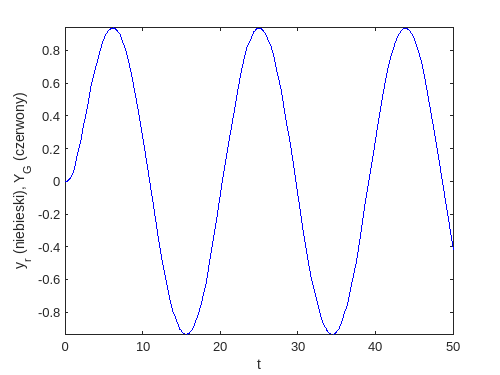

% wykreślanie przebiegów czasowych yL(t) i y_r(t) na przedziale czasu T
figure(1)
fplot(y_G(t),T,'red')
hold on
fplot(y_r(t),T,'blue')
hold off
ylabel('y_r (niebieski), Y_G (czerwony)'), xlabel('t')

Wykonać powyższą analizę dla systemu


$$\ddot{y}(t)+a_1 \dot{y}(t) + a_0 y(t) = b_1 \ddot{u} + b_0 u(t) \quad (2)$$


Przyjąć $a_1=3, ~a_0=2, ~b_1=4, ~b_0=2$,$y(0)=0, ~\dot{y}(0)=0$ oraz $u(t)=\cos(\frac{1}{3}t)$.  

 

% definicje parametrów równania różniczkowego (1)
a1=3;
a0=2;
b0=2;
b1=4

b1 = 4

% implementacja równania różniczkowego (1)
rownanie=diff(y(t),t,2)+a1*diff(y(t),t,1)+a0*y(t)== b0*u(t) +b1*diff(u(t),t,2)

$$rownanie = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+3\,\frac{\partial }{\partial t}y\left(t\right)+2\,y\left(t\right)=\frac{14\,\sin\left(\frac{t}{3}\right)}{9}$$

% specyfikacja warunków początkowych równania różniczkowego (1)
wp={0,0} % wp{1}=y(0), wp{2}=y'(0)

wp = 1×2 cell array
    {[0]}    {[0]}


% przekształcanie równania (1) przez transformatę Laplace'a
rownanieL=laplace(rownanie,t,s)

$$rownanieL = 3\,s\,\mathrm{laplace}\left(y\left(t\right),t,s\right)-3\,y\left(0\right)-s\,y\left(0\right)-\left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)+s^{2}\,\mathrm{laplace}\left(y\left(t\right),t,s\right)+2\,\mathrm{laplace}\left(y\left(t\right),t,s\right)=\frac{14}{27\,\left(s^{2}+\frac{1}{9}\right)}$$

rownanieL=subs(rownanieL,{y(0),subs(diff(y(t),t,1),t,0)},wp)

$$rownanieL = 3\,s\,\mathrm{laplace}\left(y\left(t\right),t,s\right)+s^{2}\,\mathrm{laplace}\left(y\left(t\right),t,s\right)+2\,\mathrm{laplace}\left(y\left(t\right),t,s\right)=\frac{14}{27\,\left(s^{2}+\frac{1}{9}\right)}$$

rownanieL=subs(rownanieL,{laplace(y(t),t,s), laplace(u(t),t,s)},{Y(s),U(s)})

$$rownanieL = \begin{array}{l} \frac{4}{\sigma_{1}}+\frac{2\,s^{2}}{\sigma_{1}}+\frac{2\,s}{\sigma_{2}\,\left(s^{2}+3\,s+2\right)}=\frac{14}{27\,\sigma_{2}}\\ \mathrm{where}\\ \sigma_{1}=3\,\sigma_{2}\,\left(s^{2}+3\,s+2\right)\\ \sigma_{2}=s^{2}+\frac{1}{9} \end{array}$$

rownanieL=isolate(rownanieL,Y(s))

$$rownanieL = \frac{2}{3\,\left(s^{2}+\frac{1}{9}\right)\,\left(s^{2}+3\,s+2\right)}=-\frac{-14\,s^{2}+12\,s+8}{27\,s^{6}+81\,s^{5}+57\,s^{4}+9\,s^{3}+6\,s^{2}}$$

% obliczanie transmitancji G(s) o ile jest to możliwe (warunki początkowe
% są zerowe)
if subs(rhs(rownanieL),U(s),0)==0
    rownanieL=rownanieL/U(s)
    G(s)=rhs(rownanieL)
end
% definicja zmiennej u w równaniu różniczkowym (1)
u(t)=cos(1/3*t)

$$u(t) = \cos\left(\frac{t}{3}\right)$$

% wyznaczanie reakcji na pobudzenie u(t) przy użyciu transformaty Laplace'a
% i odwrotnej transformaty Laplace'a
U(s)=laplace(u(t),t,s)

$$U(s) = \frac{s}{s^{2}+\frac{1}{9}}$$

Y(s)=G(s)*U(s)

$$Y(s) = \frac{2\,s}{\left(s^{2}+\frac{1}{9}\right)\,\left(s^{2}+3\,s+2\right)}$$

y_G(t)=simplify(ilaplace(Y(s),s,t))

$$y\_G(t) = \frac{153\,\cos\left(\frac{t}{3}\right)}{185}-\frac{9\,{\mathrm{e}}^{-t}}{5}+\frac{36\,{\mathrm{e}}^{-2\,t}}{37}+\frac{81\,\sin\left(\frac{t}{3}\right)}{185}$$

% dla porównania:
% wyznaczanie rozwiązania analitycznego równanania różniczkowego (1) dla ustalonych
% warunków początkowych
war_pocz=[y(0)==wp{1}, subs(diff(y(t),t,1),t,0)==wp{2}]

$$war\_pocz = \left(\begin{array}{cc} y\left(0\right)=0 & \left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)=0 \end{array}\right)$$

rownanie=diff(y(t),t,2)+a1*diff(y(t),t,1)+a0*y(t)== b0*u(t)

$$rownanie = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+3\,\frac{\partial }{\partial t}y\left(t\right)+2\,y\left(t\right)=2\,\cos\left(\frac{t}{3}\right)$$

rozwiazanie = dsolve(rownanie,war_pocz)

$$rozwiazanie = \frac{36\,{\mathrm{e}}^{-2\,t}}{37}-\frac{9\,{\mathrm{e}}^{-t}}{5}+\frac{9\,\sqrt{370}\,\cos\left(\frac{t}{3}-\mathrm{atan}\left(\frac{9}{17}\right)\right)}{185}$$

y_r(t)=simplify(rozwiazanie)

$$y\_r(t) = \frac{36\,{\mathrm{e}}^{-2\,t}}{37}-\frac{9\,{\mathrm{e}}^{-t}}{5}+\frac{9\,\sqrt{370}\,\cos\left(\frac{t}{3}-\mathrm{atan}\left(\frac{9}{17}\right)\right)}{185}$$

% porównanie reakcji na u(t) wyliczonej dwoma sposobami:
% przedział czasu
T=[0,50]

T =      0    50


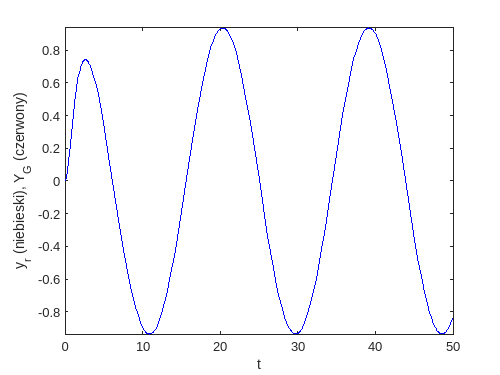

% wykreślanie przebiegów czasowych yL(t) i y_r(t) na przedziale czasu T
figure(2)
fplot(y_G(t),T,'red')
hold on
fplot(y_r(t),T,'blue')
hold off
ylabel('y_r (niebieski), Y_G (czerwony)'), xlabel('t')

Czy obydwa sposoby wyliczania $y(t)$ zwracają ten sam wynik?

**Odpowiedź.** TAK, wykresy się pokrywają

### Zadanie 2

Rozważmy transmitancję stowarzyszoną z systemem (1),


$$G(s)=\frac{b_0}{s^2+a_1 s + a_0} \quad (3)$$
 

Wyznaczyć charakterystyki amplitudową i fazową (wykresy Bodego) dla $G(s)$. Należy to zrobić na dwa sposoby: na gruncie obliczeń symbolicznych (krok po kroku) w Symbolic Math Toolbox oraz numerycznie posługując się Control System Toolbox. Można to zrobić w sposób następujący:

clear all
% SYMBOLIC MATH TOOLBOX
syms s G(s) omega G(omega) licznik(s) mianownik(s)
% definicje parametrów równania różniczkowego (1)
a1=3;
a0=2;
b0=2;
% transmitancja (3)
  licznik(s)=b0

$$licznik(s) = 2$$

mianownik(s)=(s^2+a1*s+a0)

$$mianownik(s) = s^{2}+3\,s+2$$

G(s)=licznik(s)/mianownik(s)

$$G(s) = \frac{2}{s^{2}+3\,s+2}$$

% zera i bieguny G(s)
zeraG   =solve(  licznik(s)==0,s)

 
zeraG =
 
Empty sym: 0-by-1
 


biegunyG=solve(mianownik(s)==0,s)

$$biegunyG = \left(\begin{array}{c} -2\\ -1 \end{array}\right)$$

% transmitancja widmowa stowarzyszona z (3)
G(omega)=subs(G(s), {s}, {i*omega})

$$G(omega) = \frac{2}{-\omega^{2}+3\,\omega \,\mathrm{i}+2}$$

% wektor pulsacji
om=logspace(-2,2)

om =     0.0100    0.0121    0.0146    0.0176    0.0212    0.0256    0.0309    0.0373    0.0450    0.0543    0.0655    0.0791    0.0954    0.1151    0.1389    0.1677    0.2024    0.2442    0.2947    0.3556    0.4292    0.5179    0.6251    0.7543    0.9103    1.0985    1.3257    1.5999    1.9307    2.3300    2.8118    3.3932    4.0949    4.9417    5.9636    7.1969    8.6851   10.4811   12.6486   15.2642   18.4207   22.2300   26.8270   32.3746   39.0694   47.1487   56.8987   68.6649   82.8643  100.0000


% wektory amplitud i faz G(omega) stowarzyszone z wektorem pulsacji
mG=double(  abs(subs(G(omega),{omega},{om})))

mG =     0.9999    0.9999    0.9999    0.9998    0.9997    0.9996    0.9994    0.9991    0.9987    0.9982    0.9973    0.9961    0.9943    0.9918    0.9881    0.9828    0.9752    0.9643    0.9490    0.9276    0.8985    0.8596    0.8094    0.7470    0.6731    0.5900    0.5019    0.4139    0.3309    0.2569    0.1942    0.1435    0.1041    0.0744    0.0526    0.0369    0.0257    0.0178    0.0123    0.0085    0.0059    0.0040    0.0028    0.0019    0.0013    0.0009    0.0006    0.0004    0.0003    0.0002


aG=double(angle(subs(G(omega),{omega},{om})))

aG =    -0.0150   -0.0181   -0.0218   -0.0264   -0.0318   -0.0384   -0.0463   -0.0559   -0.0674   -0.0814   -0.0982   -0.1184   -0.1428   -0.1721   -0.2074   -0.2498   -0.3005   -0.3610   -0.4329   -0.5177   -0.6168   -0.7313   -0.8615   -1.0069   -1.1656   -1.3346   -1.5099   -1.6869   -1.8607   -2.0268   -2.1816   -2.3224   -2.4477   -2.5574   -2.6519   -2.7325   -2.8006   -2.8579   -2.9059   -2.9459   -2.9792   -3.0069   -3.0299   -3.0490   -3.0649   -3.0780   -3.0889   -3.0979   -3.1054   -3.1116


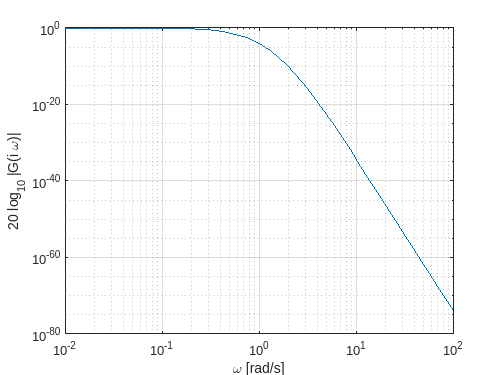

% charakterystyka amplitudowa
figure(3)
loglog(om, mG.^20)
xlabel('\omega [rad/s]')
ylabel('20 log_{10} |G(i \omega)|')
grid on

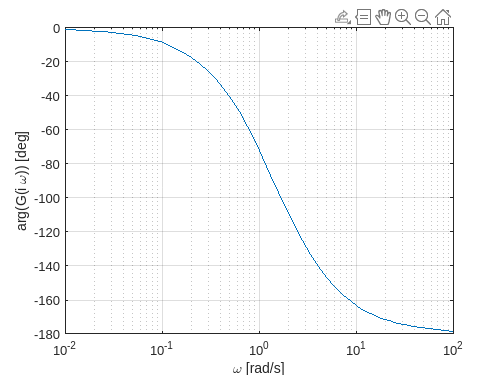

% charakterystyka fazowa
figure(4)
semilogx(om, aG*180/pi)
xlabel('\omega [rad/s]')
ylabel('arg(G(i \omega)) [deg]')
grid on

% CONTROL SYSTEM TOOLBOX
% transmitancja (3) jako obiekt klasy tf
G=tf([0,0,b0],[1,a1,a0])

G =
 
        2
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.
Model Properties


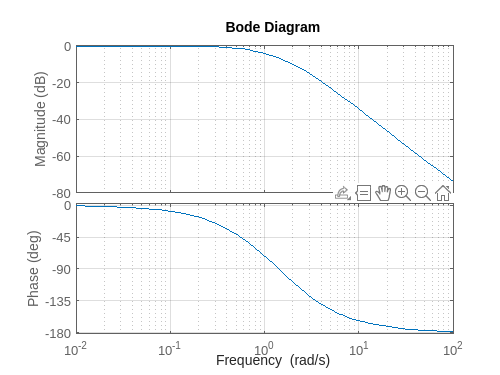

% charakterystyki amplitudowe i fazowe
figure(5)
bodeplot(G,{10^(-2), 10^2})
grid on

Wyznaczyć charakterystyki częstotliwościowe dla


$$G(s)=\frac{b_1 s +b_0}{s^2+a_1 s+a_0} \quad (4)$$


Przyjąć $a_1=3, ~a_0=2, ~b_0=2$, oraz rozważyć następujące przypadki:

- 
$$b_1=20,$$


- 
$$b_1=1.33333,$$


- 
$$b1=0.2.$$


Dla każdego przypadku wyznaczyć zera i bieguny transmitancji.

clear all
% SYMBOLIC MATH TOOLBOX
syms s G(s) omega G(omega) licznik(s) mianownik(s)
% definicje parametrów równania różniczkowego (1)
a1=3;
a0=2;
b0=2;
b1=20;
% transmitancja (3)
  licznik(s)=b0+b1*s

$$licznik(s) = 20\,s+2$$

mianownik(s)=(s^2+a1*s+a0)

$$mianownik(s) = s^{2}+3\,s+2$$

G(s)=licznik(s)/mianownik(s)

$$G(s) = \frac{20\,s+2}{s^{2}+3\,s+2}$$

% zera i bieguny G(s)
zeraG   =solve(  licznik(s)==0,s)

$$zeraG = -\frac{1}{10}$$

biegunyG=solve(mianownik(s)==0,s)

$$biegunyG = \left(\begin{array}{c} -2\\ -1 \end{array}\right)$$

% transmitancja widmowa stowarzyszona z (3)
G(omega)=subs(G(s), {s}, {i*omega})

$$G(omega) = \frac{2+20\,\omega \,\mathrm{i}}{-\omega^{2}+3\,\omega \,\mathrm{i}+2}$$

% wektor pulsacji
om=logspace(-2,2)

om =     0.0100    0.0121    0.0146    0.0176    0.0212    0.0256    0.0309    0.0373    0.0450    0.0543    0.0655    0.0791    0.0954    0.1151    0.1389    0.1677    0.2024    0.2442    0.2947    0.3556    0.4292    0.5179    0.6251    0.7543    0.9103    1.0985    1.3257    1.5999    1.9307    2.3300    2.8118    3.3932    4.0949    4.9417    5.9636    7.1969    8.6851   10.4811   12.6486   15.2642   18.4207   22.2300   26.8270   32.3746   39.0694   47.1487   56.8987   68.6649   82.8643  100.0000


% wektory amplitud i faz G(omega) stowarzyszone z wektorem pulsacji
mG=double(  abs(subs(G(omega),{omega},{om})))

mG =     1.0049    1.0072    1.0104    1.0151    1.0220    1.0318    1.0460    1.0663    1.0951    1.1358    1.1923    1.2698    1.3743    1.5125    1.6916    1.9188    2.2011    2.5446    2.9533    3.4270    3.9595    4.5345    5.1234    5.6839    6.1637    6.5084    6.6732    6.6347    6.3971    5.9909    5.4646    4.8727    4.2646    3.6778    3.1363    2.6523    2.2295    1.8660    1.5570    1.2964    1.0778    0.8952    0.7429    0.6163    0.5111    0.4237    0.3512    0.2911    0.2413    0.2000


aG=double(angle(subs(G(omega),{omega},{om})))

aG =     0.0847    0.1020    0.1228    0.1476    0.1772    0.2122    0.2533    0.3009    0.3553    0.4160    0.4818    0.5506    0.6191    0.6835    0.7396    0.7833    0.8113    0.8211    0.8108    0.7790    0.7251    0.6488    0.5506    0.4321    0.2958    0.1454   -0.0144   -0.1785   -0.3416   -0.4989   -0.6464   -0.7811   -0.9014   -1.0068   -1.0978   -1.1756   -1.2413   -1.2967   -1.3430   -1.3816   -1.4138   -1.4406   -1.4629   -1.4813   -1.4966   -1.5093   -1.5198   -1.5286   -1.5358   -1.5418


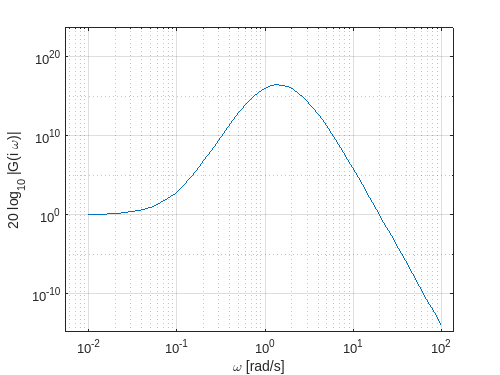

% charakterystyka amplitudowa
figure(6)
loglog(om, mG.^20)
xlabel('\omega [rad/s]')
ylabel('20 log_{10} |G(i \omega)|')
grid on

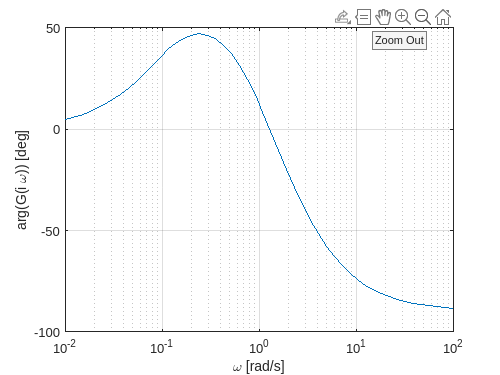

% charakterystyka fazowa
figure(7)
semilogx(om, aG*180/pi)
xlabel('\omega [rad/s]')
ylabel('arg(G(i \omega)) [deg]')
grid on

% CONTROL SYSTEM TOOLBOX
% transmitancja (3) jako obiekt klasy tf
G=tf([0,0,b0],[1,a1,a0])

G =
 
        2
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.
Model Properties


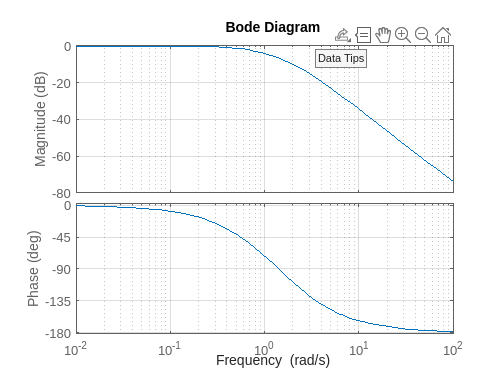

% charakterystyki amplitudowe i fazowe
figure(8)
bodeplot(G,{10^(-2), 10^2})
grid on

Jaki wpływ na charakterystyki częstotliwościowe amplitudy i fazy ma wzajemne położenie zer i biegunów transmitancji?

**Odpowiedź.**  Zera układu powodują zmianę nachylenia o +20dB/dek i zwiekszaja faze o pi/2, a bieguny o -20db/dek i zmniejszaja faze o pi/2

### Zadanie 3

Rozważmy transmitancję stowarzyszoną z systemem (3). Wyznaczyć odpowiedź impulsową, tzn. $k(t)=\mathcal{L}^{-1}(G(s))$ w formie analitycznej oraz wykreślić przebieg tej funkcji w czasie na wykresie. Niech $u(t)=\cos(\frac{1}{3} t)$, $U(s)=\mathcal{L}\{ u(t)\}$.

Obliczyć

-  
$$Y(s)=G(s) \cdot U(s), \quad y_G(t)=\mathcal{L}^{-1}\{ Y(s)\}$$


- 
$$y_k(t)=\int_0^t k(t-\tau) u(\tau) d \tau$$


Sprawdzić analitycznie, że $y_k(t) = y_G(t) ~\forall t$. Przedstawić na jednym wykresie $y_k(t)$ i $u(t)$. 

Sprawdzić analitycznie, że dla $y_k(t)$ i stowarzysznego z nim $u(t)$ spełnione jest równanie (1) (innymi słowy jeśli do tego równania podstawimy $y_k(t)$ i $u(t)$ to lewa strona będzie równa prawej).

Powyższe zadanie można zrealizować w sposób następujący:

clear all
% SYMBOLIC MATH TOOLBOX
syms s G(s) omega G(omega) licznik(s) mianownik(s) t tau
% definicje parametrów równania różniczkowego (1)
a1=3;
a0=2;
b0=2;
% pobudzenie
u(t)=cos(1/3*t)

$$u(t) = \cos\left(\frac{t}{3}\right)$$

U(s)=laplace(u(t),t,s)

$$U(s) = \frac{s}{s^{2}+\frac{1}{9}}$$

% transmitancja (3)
  licznik(s)=b0

$$licznik(s) = 2$$

mianownik(s)=(s^2+a1*s+a0)

$$mianownik(s) = s^{2}+3\,s+2$$

G(s)=licznik(s)/mianownik(s)

$$G(s) = \frac{2}{s^{2}+3\,s+2}$$

Y(s)=G(s)*U(s)

$$Y(s) = \frac{2\,s}{\left(s^{2}+\frac{1}{9}\right)\,\left(s^{2}+3\,s+2\right)}$$

% odpowiedź impulsowa stowarzyszona z (3)
k(t)=ilaplace(G(s),s,t)

$$k(t) = 2\,{\mathrm{e}}^{-t}-2\,{\mathrm{e}}^{-2\,t}$$

T=[0,50]

T =      0    50


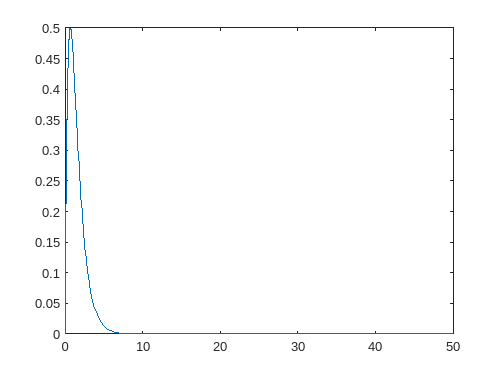

figure
fplot(k(t),T)

y_G(t)=ilaplace(Y(s),s,t)

$$y\_G(t) = \frac{153\,\cos\left(\frac{t}{3}\right)}{185}-\frac{9\,{\mathrm{e}}^{-t}}{5}+\frac{36\,{\mathrm{e}}^{-2\,t}}{37}+\frac{81\,\sin\left(\frac{t}{3}\right)}{185}$$

y_k(t)=int(k(t-tau)*u(tau),tau,[0,t])

$$y\_k(t) = \frac{153\,\cos\left(\frac{t}{3}\right)}{185}-\frac{9\,{\mathrm{e}}^{-t}}{5}+\frac{36\,{\mathrm{e}}^{-2\,t}}{37}+\frac{81\,\sin\left(\frac{t}{3}\right)}{185}$$

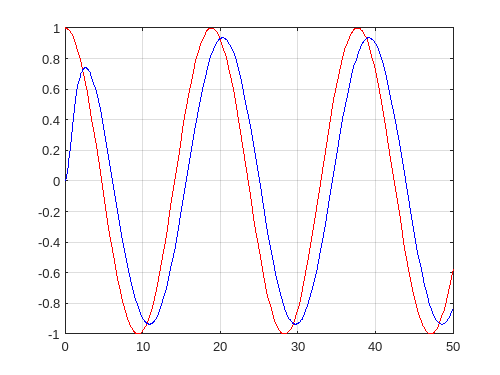

figure
fplot(u(t),T,'red')
hold on
fplot(y_k(t),T,'blue')
hold off
grid on

% sprawdzenie, że y_k(t) i u(t) spełniają równanie różniczkowe (1)
if simplify(diff(y_k(t),t,2)+a1*diff(y_k(t),t,1)+a0*y_k(t))== b0*u(t) ...
    disp(':)'); ...
else ...
    disp(':('); ...
end

:)


Nietrudno zauważyć, że reakcją na pobudzenie cosinusoidalne jest sygnał zawierający składową przejściową i składową ustaloną, gdzie ta ostatnia ma postać $A \cos( \omega t) + B \sin(\omega t). $ To wyrażenie może być przekształcone do postaci $C \cos(\omega t - \varphi)$, gdzie $C=\sqrt{A^2+B^2}$, $\tan \varphi = \frac{B}{A}$. Zatem jest to również sygnał cosinusoidalny o nieco innej amplitudzie i fazie względem pobudzenia (w stanie ustalonym). 

Jaki jest związek tej obserwacji z charakterystyką amplitudowo-fazową wyznaczaną w zadaniu 2-gim?

**Odpowiedź.** tbd.

Powtórzyć powyższe zadanie dla transmitancji (4). Przyjąć $a_1=3, ~a_0=2, ~b_0=2$, oraz rozważyć następujące przypadki:

- 
$$b_1=20,$$


- 
$$b_1=1.33333,$$


- 
$$b1=0.2.$$


clear all
% SYMBOLIC MATH TOOLBOX
syms s G(s) omega G(omega) licznik(s) mianownik(s) t tau
% definicje parametrów równania różniczkowego (1)
a1=3;
a0=2;
b0=2;
b1=20

b1 = 20

% pobudzenie
u(t)=cos(1/3*t)

$$u(t) = \cos\left(\frac{t}{3}\right)$$

U(s)=laplace(u(t),t,s)

$$U(s) = \frac{s}{s^{2}+\frac{1}{9}}$$

% transmitancja (3)
  licznik(s)=b0 +b1*s

$$licznik(s) = 20\,s+2$$

mianownik(s)=(s^2+a1*s+a0)

$$mianownik(s) = s^{2}+3\,s+2$$

G(s)=licznik(s)/mianownik(s)

$$G(s) = \frac{20\,s+2}{s^{2}+3\,s+2}$$

Y(s)=G(s)*U(s)

$$Y(s) = \frac{s\,\left(20\,s+2\right)}{\left(s^{2}+\frac{1}{9}\right)\,\left(s^{2}+3\,s+2\right)}$$

% odpowiedź impulsowa stowarzyszona z (3)
k(t)=ilaplace(G(s),s,t)

$$k(t) = 38\,{\mathrm{e}}^{-2\,t}-18\,{\mathrm{e}}^{-t}$$

T=[0,50]

T =      0    50


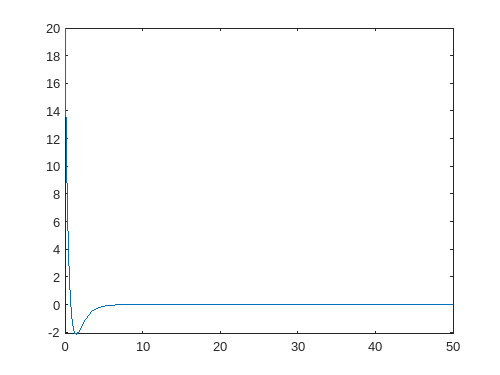

figure
fplot(k(t),T)

y_G(t)=ilaplace(Y(s),s,t)

$$y\_G(t) = \frac{423\,\cos\left(\frac{t}{3}\right)}{185}+\frac{81\,{\mathrm{e}}^{-t}}{5}-\frac{684\,{\mathrm{e}}^{-2\,t}}{37}-\frac{429\,\sin\left(\frac{t}{3}\right)}{185}$$

y_k(t)=int(k(t-tau)*u(tau),tau,[0,t])

$$y\_k(t) = \frac{423\,\cos\left(\frac{t}{3}\right)}{185}+\frac{81\,{\mathrm{e}}^{-t}}{5}-\frac{684\,{\mathrm{e}}^{-2\,t}}{37}-\frac{429\,\sin\left(\frac{t}{3}\right)}{185}$$

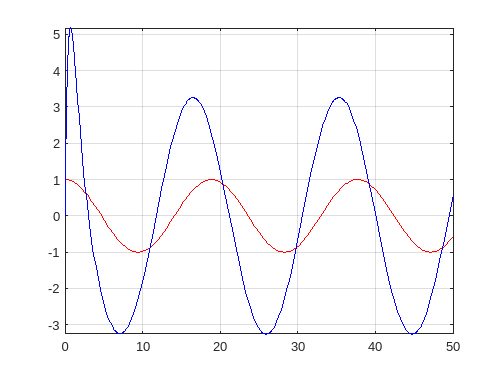

figure
fplot(u(t),T,'red')
hold on
fplot(y_k(t),T,'blue')
hold off
grid on

% sprawdzenie, że y_k(t) i u(t) spełniają równanie różniczkowe (1)
if simplify(diff(y_k(t),t,2)+a1*diff(y_k(t),t,1)+a0*y_k(t))== b0*u(t) ...
    disp(':)'); ...
else ...
    disp(':('); ...
end

:(


**Odpowiedź.** tbd.